close all
clear
clc

准备工作

[t,omg,FT,IFT] = prefourier([-1,2],300,[-50,50],100);

定义矩形脉冲

tau = 0.5;
v1 = (t>0&t<tau);

定义滤波器频响

R = 1; C = 0.3;
alpha = 1/R/C;
H = alpha./(alpha+1j*omg);

计算激励的频谱，计算响应的频谱

V1 = FT*v1;
V2 = V1.*H;

对两个频谱分别逆变换得到冲激响应和系统输出

h = IFT*H;
v2 = IFT*V2;

绘图：左侧是波形，右侧是频谱，自上而下依次是冲激响应、激励和输出

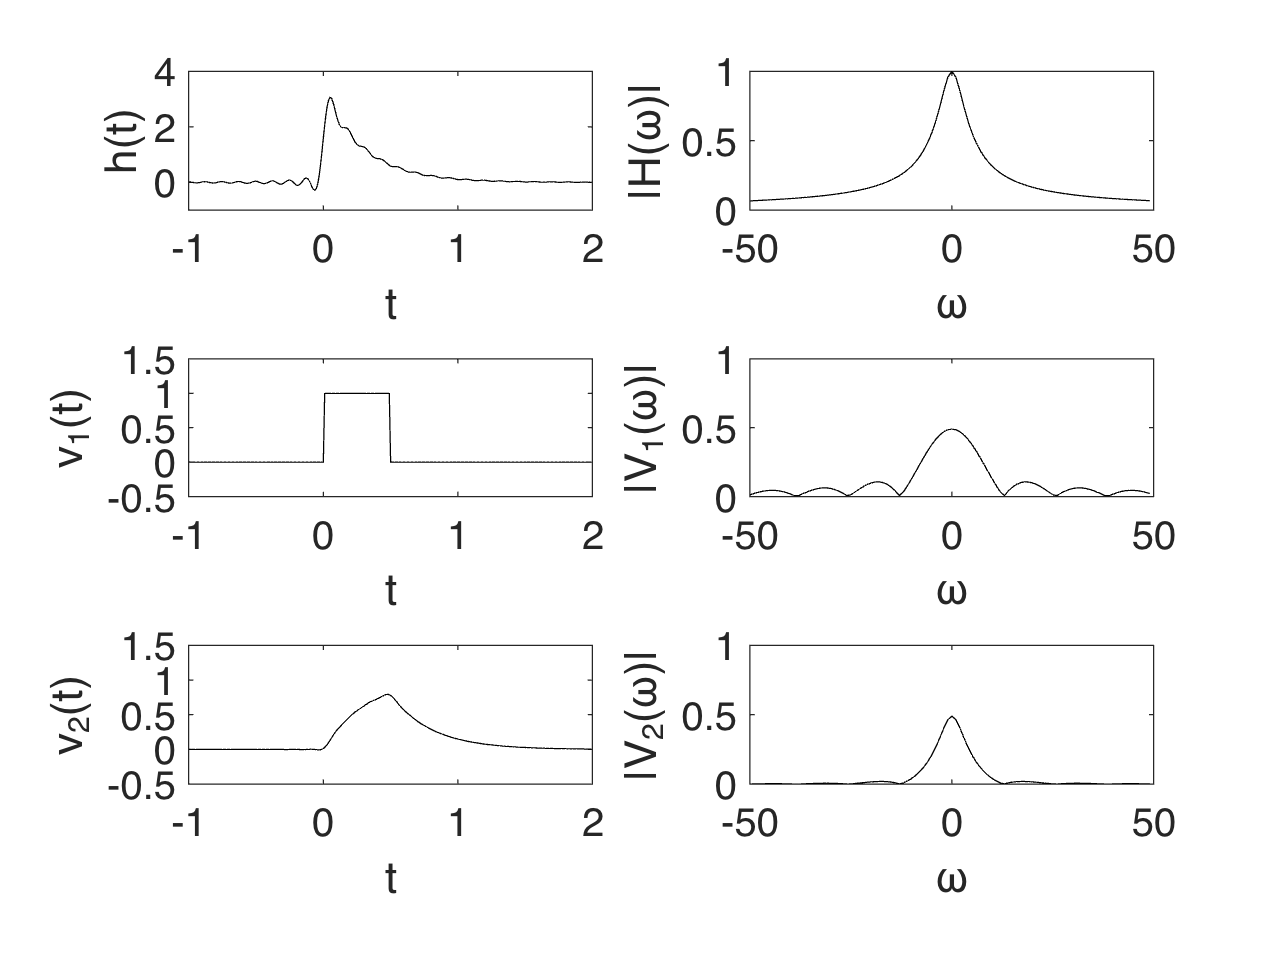

figure;
subplot(3,2,1), hold on, box on;
plot(t, real(h), 'k-');
set(gca,'YLim',[-1,4],'XLim',[-1,2],'FontSize',16);
xlabel('t');
ylabel('h(t)');

subplot(3,2,2), hold on, box on;
plot(omg, abs(H),'k-');
set(gca,'YLim',[0,1],'FontSize',16);
xlabel('\omega');
ylabel('|H(\omega)|');

subplot(3,2,3), hold on, box on;
plot(t, v1, 'k-');
set(gca,'FontSize',16);
axis([-1 2 -0.5 1.5]);
xlabel('t');
ylabel('v_1(t)');

subplot(3,2,4), hold on, box on;
plot(omg,abs(V1),'k-'); %axis tight;
set(gca,'YLim',[0 1],'FontSize',16);
xlabel('\omega');
ylabel('|V_1(\omega)|');

subplot(3,2,5), hold on, box on; 
plot(t, real(v2),'k-');
set(gca,'YLim',[-0.5 1.5],'XLim',[-1,2],'FontSize', 16);
xlabel('t');
ylabel('v_2(t)');

subplot(3,2,6), hold on, box on;
plot(omg,abs(V2),'k-'); %axis tight;
set(gca,'YLim',[0 1],'FontSize',16);
xlabel('\omega');
ylabel('|V_2(\omega)|');